Removed overssampling on ends of normal convolving window.

Removed false start trials, changed them from being considered correct to incorrect

### Load in data and compile

cd("C:\Users\djlasky\OneDrive - University of California, Davis\Documents\UC Davis\Usrey Lab\Analysis");
trialBlocks = 52;

trialCorrect    = cell(trialBlocks, 1);
trialValidity   = cell(trialBlocks, 1);
trialRT         = cell(trialBlocks, 1);
S1OnTime        = cell(trialBlocks, 1);
S1OffTime       = cell(trialBlocks, 1);

for n = 1:trialBlocks
    fileName = sprintf("DannyLinearS1_%d.mat", n);
    data = load(fileName);
    trialCorrect{n}     = data.trialCorrect;
    trialValidity{n}    = data.valid;
    trialRT{n}          = data.trialRT;
    S1OnTime{n}         = data.stim1OnsetTime;
    S1OffTime{n}        = data.stim1OffsetTime;
end

trialCorrect    = horzcat(trialCorrect{:});
trialValidity   = horzcat(trialValidity{:});
trialRT         = horzcat(trialRT{:});
S1OnTime        = horzcat(S1OnTime{:});
S1OffTime       = horzcat(S1OffTime{:});

trialValid      = trialValidity == 1;
trialInvalid    = trialValidity == 0;
trialCatch      = trialValidity == -1;

trueCorrect = trialCorrect == 1 & trialRT >= 285;

correctValid    = trueCorrect & trialValid;
correctInvalid  = trueCorrect & trialInvalid;
correctCatch    = trialCorrect == 1 & trialCatch;

correctOnlyValid = trueCorrect(trialValid);

myColor = flipud(parula);

### Calculate valid trial hit rate vs S1 duration with different moving averages

S1Timing = (S1OffTime - S1OnTime) * 1000;       % Convert to msec
validS1 = round(S1Timing(trialValid));

correctValidS1 = round(S1Timing(correctValid));
uniqueS1 = unique(validS1);
uniqueS1 = uniqueS1(1:72);      % Importantly removes two trials in which the S1 duration was one frame longer than max (1717 msec)

validS1HitRate = nan(length(uniqueS1), 1);
for n = 1:length(uniqueS1)
    loopValid = sum(ismember(validS1, uniqueS1(n)));
    loopValidCorrect = sum(ismember(correctValidS1, uniqueS1(n)));
    validS1HitRate(n) = loopValidCorrect / loopValid;
end

hitRateMoveMean50 = movmean(validS1HitRate, 3);
hitRateMoveMean83 = movmean(validS1HitRate, 5);
hitRateMoveMean117 = movmean(validS1HitRate, 7);

hitRateMoveMean50 = hitRateMoveMean50(2:end-1);
hitRateMoveMean83 = hitRateMoveMean83(3:end-2);
hitRateMoveMean117 = hitRateMoveMean117(4:end-3);

signalLength50 = length(hitRateMoveMean50);
signalLength83 = length(hitRateMoveMean83);
signalLength117 = length(hitRateMoveMean117);

samplingFreqMoveMean = 60;

hitRateMoveMean50H = hitRateMoveMean50 .* hann(height(hitRateMoveMean50));
hitRateMoveMean83H = hitRateMoveMean83 .* hann(height(hitRateMoveMean83));
hitRateMoveMean117H = hitRateMoveMean117 .* hann(height(hitRateMoveMean117));

hitRateMoveMean50HP = [hitRateMoveMean50H; zeros(530, 1)];
hitRateMoveMean83HP = [hitRateMoveMean83H; zeros(532, 1)];
hitRateMoveMean117HP = [hitRateMoveMean117H; zeros(534, 1)];

signalLengthExp = height(hitRateMoveMean50HP);

FFT_HitRateMoveMean50 = fft(hitRateMoveMean50HP, signalLengthExp);
FFT_HitRateMoveMean83 = fft(hitRateMoveMean83HP, signalLengthExp);
FFT_HitRateMoveMean117 = fft(hitRateMoveMean117HP, signalLengthExp);

xValsMoveMeanHP = (0:(signalLengthExp - 1)) * samplingFreqMoveMean/signalLengthExp;       % Freq resolution = 0.1; (0:(signalLength - 1)) * (samplingFreq/signalLength)

### Calculate valid trial hit rate vs S1 duration with different Kastner averages

startWindow = 500;
endWindow = [550, 575, 600];
hitRateKastner50 = nan(1150, 1);
hitRateKastner75 = nan(1125, 1);
hitRateKastner100 = nan(1100, 1);

for n = 1:1150
    window50 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(1) + n - 1;
    hitRateKastner50(n) = sum(correctValid(window50), "all") / sum(trialValid(window50), "all");
end
for n = 1:1125
    window75 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(2) + n - 1;
    hitRateKastner75(n) = sum(correctValid(window75), "all") / sum(trialValid(window75), "all");
end
for n = 1:1100
    window100 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(3) + n - 1;
    hitRateKastner100(n) = sum(correctValid(window100), "all") / sum(trialValid(window100), "all");
end

xStartKastner = [526, 538.5, 551];
xEndKastner = [1675, 1662.5, 1650];

hitRateKastner50Smooth = movmean(hitRateKastner50, 25);
hitRateKastner75Smooth = movmean(hitRateKastner75, 25);
hitRateKastner100Smooth = movmean(hitRateKastner100, 25);

hitRateKastner50H = hitRateKastner50Smooth .* hann(height(hitRateKastner50Smooth));
hitRateKastner75H = hitRateKastner75Smooth .* hann(height(hitRateKastner75Smooth));
hitRateKastner100H = hitRateKastner100Smooth .* hann(height(hitRateKastner100Smooth));

hitRateKastner50HP = [hitRateKastner50H; zeros(8850, 1)];
hitRateKastner75HP = [hitRateKastner75H; zeros(8875, 1)];
hitRateKastner100HP = [hitRateKastner100H; zeros(8900, 1)];

signalLengthKastnerHP = height(hitRateKastner50HP);

FFT_hitRateKastner50 = fft(hitRateKastner50HP);
FFT_hitRateKastner75 = fft(hitRateKastner75HP);
FFT_hitRateKastner100 = fft(hitRateKastner100HP);

samplingFreqKastner = 1000;
xValsKastnerHP = (0:(signalLengthKastnerHP - 1)) * samplingFreqKastner/signalLengthKastnerHP;       % Freq resolution = 0.1; (0:(signalLength - 1)) * (samplingFreq/signalLength)

### Hit rate for 100 ms only plots

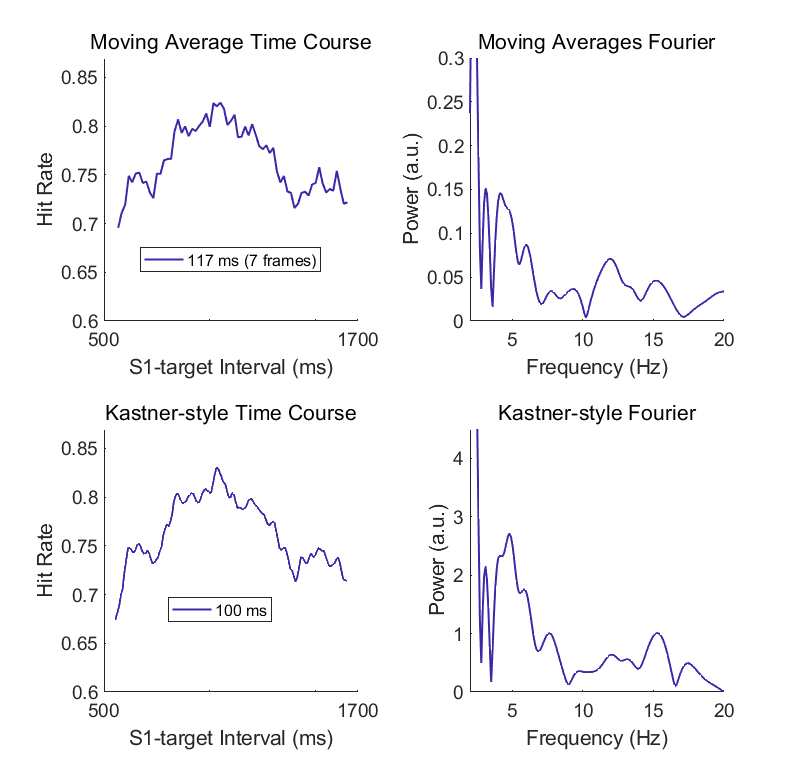

uniqueS1_50 = uniqueS1(2:end-1);
uniqueS1_83 = uniqueS1(3:end-2);
uniqueS1_117 = uniqueS1(4:end-3);

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, hitRateMoveMean117, "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0.6 0.87])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend("117 ms (7 frames)", "FontSize", 12, "Position", [0.1756, 0.6500, 0.2262, 0.0322])
nexttile
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean117), "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xlim([2 20])
    ylim([0 0.3])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), hitRateKastner100Smooth, "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0.6 0.87])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend("100 ms", "FontSize", 12, "Position", [0.2103, 0.2, 0.1300, 0.0322])
nexttile
    plot(xValsKastnerHP, abs(FFT_hitRateKastner100), "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xlim([2 20])
    ylim([0 4.5])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Valid Hit Rate 100 msec.png", 'Resolution', 300)

### Hit rate for 75–100 ms plots

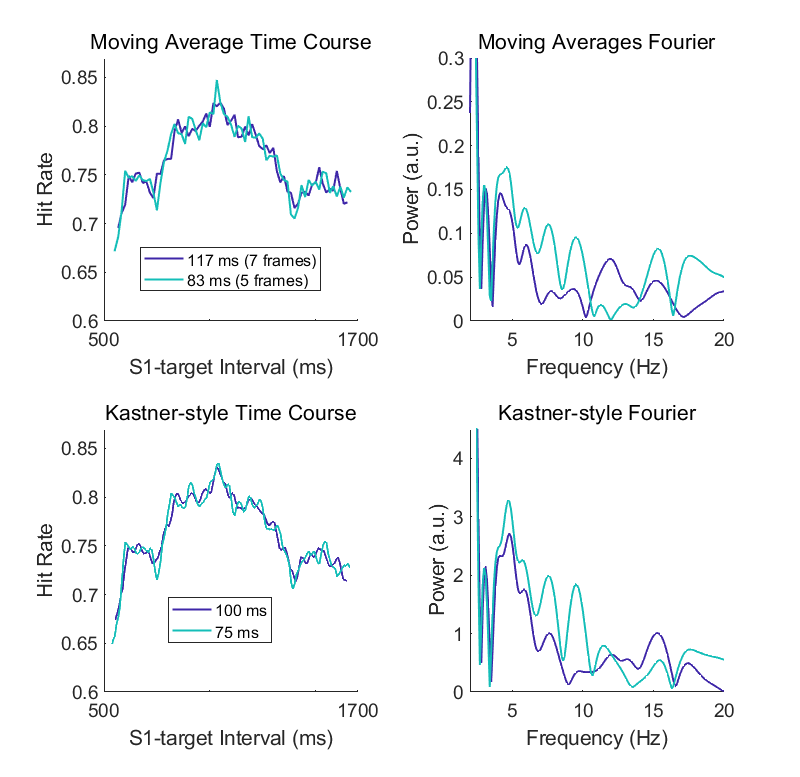

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, hitRateMoveMean117, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(uniqueS1_83, hitRateMoveMean83, "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0.6 0.87])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend(["117 ms (7 frames)", "83 ms (5 frames)"], "FontSize", 12, "Position", [0.1756, 0.6261, 0.2262, 0.0561])
nexttile
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean117), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean83), "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xlim([2 20])
    ylim([0 0.3])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), hitRateKastner100Smooth, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xStartKastner(2):xEndKastner(2), hitRateKastner75Smooth, "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0.6 0.87])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend(["100 ms", "75 ms"], "FontSize", 12, "Position", [0.2103, 0.1724, 0.1300, 0.0598])
nexttile
    plot(xValsKastnerHP, abs(FFT_hitRateKastner100), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsKastnerHP, abs(FFT_hitRateKastner75), "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xlim([2 20])
    ylim([0 4.5])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Valid Hit Rate 75–100 msec.png", 'Resolution', 300)

### Hit rate for 50–100 ms plots

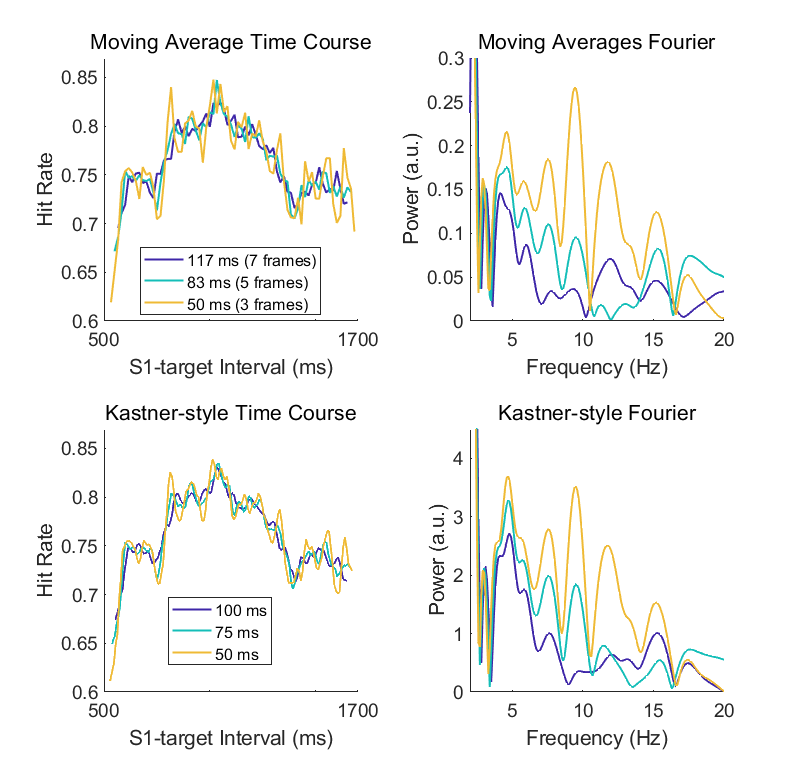

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, hitRateMoveMean117, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(uniqueS1_83, hitRateMoveMean83, "Color", myColor(128,:), "LineWidth", 1.5)
    plot(uniqueS1_50, hitRateMoveMean50, "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0.6 0.87])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend(["117 ms (7 frames)", "83 ms (5 frames)", "50 ms (3 frames)"], "FontSize", 12, "Position", [0.1756, 0.5947, 0.2262, 0.0875])
nexttile
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean117), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean83), "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean50), "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xlim([2 20])
    ylim([0 0.3])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), hitRateKastner100Smooth, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xStartKastner(2):xEndKastner(2), hitRateKastner75Smooth, "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xStartKastner(1):xEndKastner(1), hitRateKastner50Smooth, "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0.6 0.87])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend(["100 ms", "75 ms", "50 ms"], "FontSize", 12, "Position", [0.2103, 0.1447, 0.1300, 0.0875])
nexttile
    plot(xValsKastnerHP, abs(FFT_hitRateKastner100), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsKastnerHP, abs(FFT_hitRateKastner75), "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xValsKastnerHP, abs(FFT_hitRateKastner50), "Color", myColor(50,:), "LineWidth", 1.5)
    hold on
    hold off; box off
    xlim([2 20])
    ylim([0 4.5])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Valid Hit Rate 50–100 msec.png", 'Resolution', 300)

### Calculate random permutations line for 100 msec valid trial hit rate

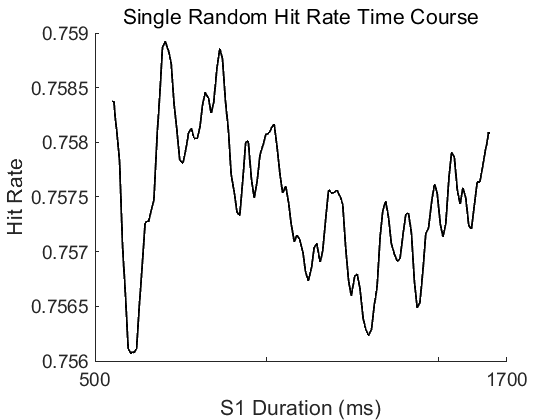

numPermutations = 1000;
hitRateKastner100Rand = nan(1100, numPermutations);
window100Rand = 500:1600;

for m = 1:numPermutations
    correctRandom = correctOnlyValid(randperm(length(correctOnlyValid)));
    for n = 1:1100
        windowTrials100 = validS1 >= window100Rand(n) & validS1 <= window100Rand(n) + 100;
        hitRateKastner100Rand(n, m) = sum(correctRandom(windowTrials100), "all") / sum(windowTrials100, "all");
    end
end

hitRateKastner100Rand = movmean(hitRateKastner100Rand, 25, 1);   % 25 point boxcar smoothing
xValKastner100 = 551:1650;

figure
plot(xStartKastner(3):xEndKastner(3), mean(hitRateKastner100Rand, 2), "k", "LineWidth", 1.5)
box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])
ax = gca;
ax.FontSize = 14;
title("Single Random Hit Rate Time Course", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Hit Rate", "FontSize", 16)

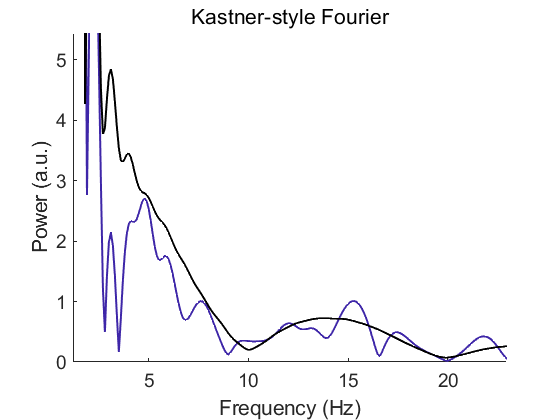


hitRateKastner100RandH = hitRateKastner100Rand .* hann(height(hitRateKastner100Rand));
hitRateKastner100RandHP = [hitRateKastner100RandH; zeros(8900, width(hitRateKastner100RandH))];

FFT_hitRateKastner100Rand = fft(hitRateKastner100RandHP);

FFT_hitRateKastner100Rand_Mn = mean(abs(FFT_hitRateKastner100Rand), 2);
FFT_hitRateKastner100Rand_Sd = std(abs(FFT_hitRateKastner100Rand), [], 2);

figure
plot(xValsKastnerHP, abs(FFT_hitRateKastner100), "Color", myColor(256,:), "LineWidth", 1.5)
hold on
plot(xValsKastnerHP, abs(FFT_hitRateKastner100Rand_Mn), "k", "LineWidth", 1.5)
hold off; box off
xlim([2 20])
ylim([0 4.5])
ax = gca;
ax.FontSize = 14;
title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
xlabel("Frequency (Hz)")
ylabel("Power (a.u.)")

### Calculate random permutations line for 50 msec valid trial hit rate

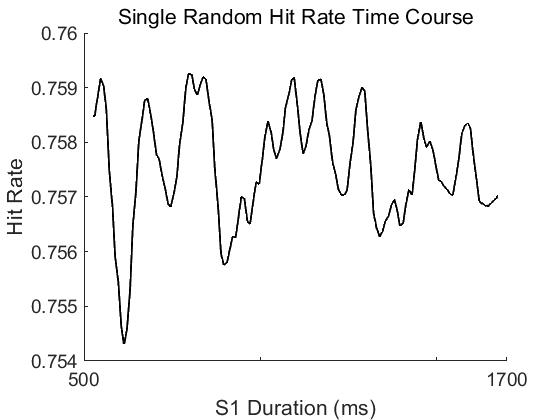

numPermutations = 1000;
hitRateKastner50Rand = nan(1150, numPermutations);
window50Rand = 500:1650;

for m = 1:numPermutations
    correctRandom = correctOnlyValid(randperm(length(correctOnlyValid)));
    for n = 1:1150
        windowTrials50 = validS1 >= window50Rand(n) & validS1 <= window50Rand(n) + 50;
        hitRateKastner50Rand(n, m) = sum(correctRandom(windowTrials50), "all") / sum(windowTrials50, "all");
    end
end

hitRateKastner50Rand = movmean(hitRateKastner50Rand, 25, 1);   % 25 point boxcar smoothing
xValKastner50 = 526:1675;

figure
plot(xStartKastner(1):xEndKastner(1), mean(hitRateKastner50Rand, 2), "k", "LineWidth", 1.5)
box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])
ax = gca;
ax.FontSize = 14;
title("Single Random Hit Rate Time Course", "FontSize", 16, "FontWeight", "normal")
xlabel("S1 Duration (ms)", "FontSize", 16)
ylabel("Hit Rate", "FontSize", 16)

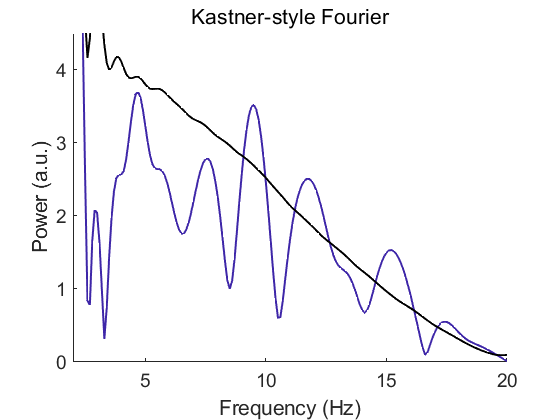


hitRateKastner50RandH = hitRateKastner50Rand .* hann(height(hitRateKastner50Rand));
hitRateKastner50RandHP = [hitRateKastner50RandH; zeros(8850, width(hitRateKastner50RandH))];

FFT_hitRateKastner50Rand = fft(hitRateKastner50RandHP);

FFT_hitRateKastner50Rand_Mn = mean(abs(FFT_hitRateKastner50Rand), 2);
FFT_hitRateKastner50Rand_Sd = std(abs(FFT_hitRateKastner50Rand), [], 2);

figure
plot(xValsKastnerHP, abs(FFT_hitRateKastner50), "Color", myColor(256,:), "LineWidth", 1.5)
hold on
plot(xValsKastnerHP, abs(FFT_hitRateKastner50Rand_Mn), "k", "LineWidth", 1.5)
hold off; box off
xlim([2 20])
ylim([0 4.5])
ax = gca;
ax.FontSize = 14;
title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
xlabel("Frequency (Hz)")
ylabel("Power (a.u.)")

### Recreate major findings plot with reaction time

correctValidRT  = trialRT(correctValid);
correctValidS1RT = nan(length(uniqueS1), 1);

for n = 1:length(uniqueS1)
    loopValid = ismember(correctValidS1, uniqueS1(n));
    correctValidS1RT(n) = mean(correctValidRT(loopValid));
end

RTMoveMean50 = movmean(correctValidS1RT, 3);
RTMoveMean83 = movmean(correctValidS1RT, 5);
RTMoveMean117 = movmean(correctValidS1RT, 7);

RTMoveMean50 = RTMoveMean50(2:end-1);
RTMoveMean83 = RTMoveMean83(3:end-2);
RTMoveMean117 = RTMoveMean117(4:end-3);

RTMoveMean50H = RTMoveMean50 .* hann(height(RTMoveMean50));
RTMoveMean83H = RTMoveMean83 .* hann(height(RTMoveMean83));
RTMoveMean117H = RTMoveMean117 .* hann(height(RTMoveMean117));

RTMoveMean50HP = [RTMoveMean50H; zeros(530, 1)];
RTMoveMean83HP = [RTMoveMean83H; zeros(532, 1)];
RTMoveMean117HP = [RTMoveMean117H; zeros(534, 1)];

FFT_RTMoveMean50 = fft(RTMoveMean50HP, signalLengthExp);
FFT_RTMoveMean83 = fft(RTMoveMean83HP, signalLengthExp);
FFT_RTMoveMean117 = fft(RTMoveMean117HP, signalLengthExp);

RTKastner50    = nan(1150, 1);
RTKastner75    = nan(1125, 1);
RTKastner100   = nan(1100, 1);

for n = 1:1150
    window50 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(1) + n - 1;
    RTKastner50(n) = mean(trialRT(window50 & correctValid));  
end
for n = 1:1125
    window75 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(2) + n - 1;
    RTKastner75(n) = mean(trialRT(window75 & correctValid));  
end
for n = 1:1100
    window100 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(3) + n - 1;
    RTKastner100(n) = mean(trialRT(window100 & correctValid));  
end

RTKastner50Smooth = movmean(RTKastner50, 25);
RTKastner75Smooth = movmean(RTKastner75, 25);
RTKastner100Smooth = movmean(RTKastner100, 25);

RTKastner50H = RTKastner50Smooth .* hann(height(RTKastner50Smooth));
RTKastner75H = RTKastner75Smooth .* hann(height(RTKastner75Smooth));
RTKastner100H = RTKastner100Smooth .* hann(height(RTKastner100Smooth));

RTKastner50HP = [RTKastner50H; zeros(8850, 1)];
RTKastner75HP = [RTKastner75H; zeros(8875, 1)];
RTKastner100HP = [RTKastner100H; zeros(8900, 1)];

FFT_RTKastner50 = fft(RTKastner50HP);
FFT_RTKastner75 = fft(RTKastner75HP);
FFT_RTKastner100 = fft(RTKastner100HP);

### Reaction time for 100 ms only plots

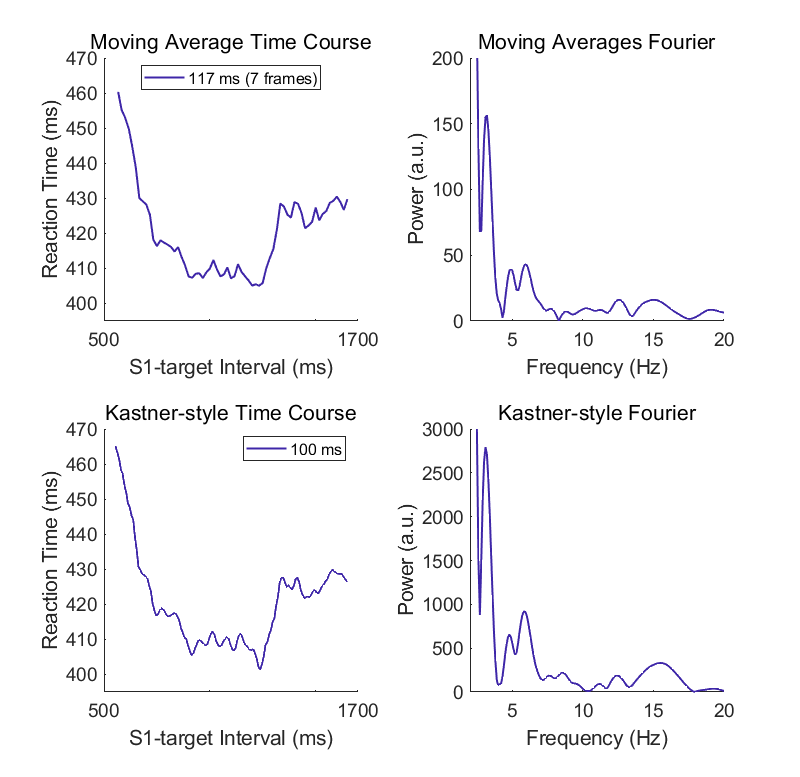

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, RTMoveMean117, "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([395 470])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Reaction Time (ms)")
    legend("117 ms (7 frames)", "FontSize", 12, "Location", "best")
nexttile
plot(xValsMoveMeanHP, abs(FFT_RTMoveMean117), "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xlim([2 20])
    ylim([0 200])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), RTKastner100Smooth, "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([395 470])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Reaction Time (ms)")
    legend("100 ms", "FontSize", 12, "Location", "best")
nexttile
    plot(xValsKastnerHP, abs(FFT_RTKastner100), "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xlim([2 20])
    ylim([0 3000])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Valid RT 50–100 msec.png", 'Resolution', 300)

### Reaction time for 75–100 ms plots

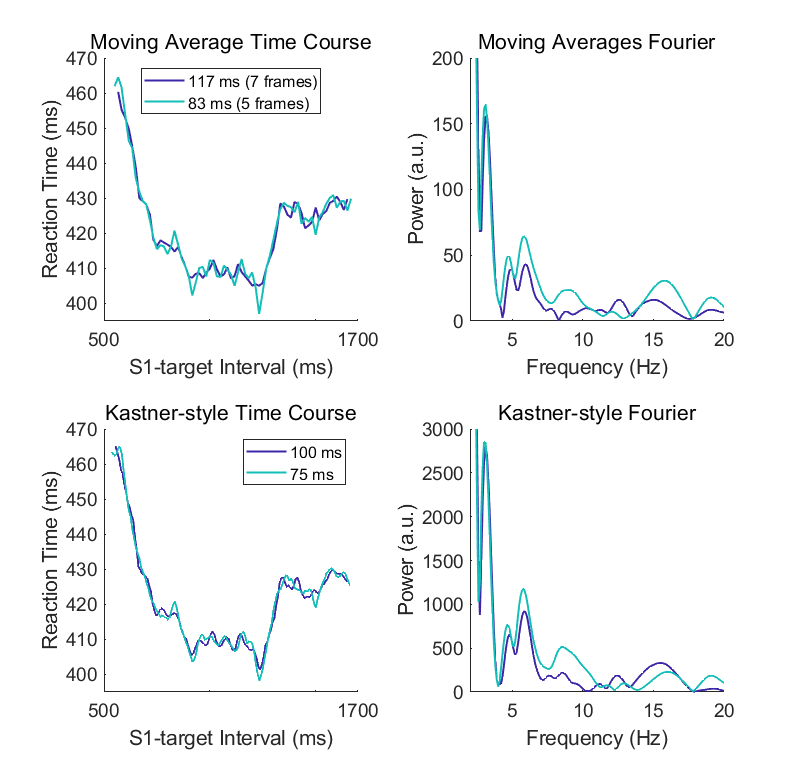

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, RTMoveMean117, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(uniqueS1_83, RTMoveMean83, "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([395 470])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Reaction Time (ms)")
    legend(["117 ms (7 frames)", "83 ms (5 frames)"], "FontSize", 12, "Location", "best")
nexttile
plot(xValsMoveMeanHP, abs(FFT_RTMoveMean117), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsMoveMeanHP, abs(FFT_RTMoveMean83), "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xlim([2 20])
    ylim([0 200])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), RTKastner100Smooth, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xStartKastner(2):xEndKastner(2), RTKastner75Smooth, "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([395 470])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Reaction Time (ms)")
    legend(["100 ms", "75 ms"], "FontSize", 12, "Location", "best")
nexttile
    plot(xValsKastnerHP, abs(FFT_RTKastner100), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsKastnerHP, abs(FFT_RTKastner75), "Color", myColor(128,:), "LineWidth", 1.5)
    hold on
    hold off; box off
    xlim([2 20])
    ylim([0 3000])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Valid RT 75–100 msec.png", 'Resolution', 300)

### Reaction time for 50–100 ms plots

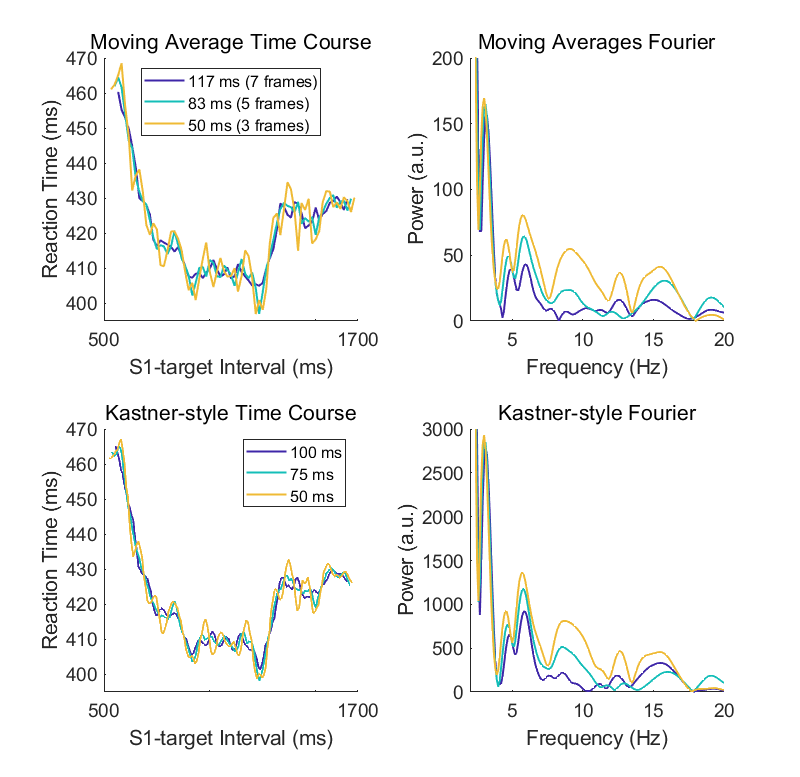

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, RTMoveMean117, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(uniqueS1_83, RTMoveMean83, "Color", myColor(128,:), "LineWidth", 1.5)
    plot(uniqueS1_50, RTMoveMean50, "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([395 470])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Reaction Time (ms)")
    legend(["117 ms (7 frames)", "83 ms (5 frames)", "50 ms (3 frames)"], "FontSize", 12, "Location", "best")
nexttile
plot(xValsMoveMeanHP, abs(FFT_RTMoveMean117), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsMoveMeanHP, abs(FFT_RTMoveMean83), "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xValsMoveMeanHP, abs(FFT_RTMoveMean50), "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xlim([2 20])
    ylim([0 200])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), RTKastner100Smooth, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xStartKastner(2):xEndKastner(2), RTKastner75Smooth, "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xStartKastner(1):xEndKastner(1), RTKastner50Smooth, "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([395 470])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Reaction Time (ms)")
    legend(["100 ms", "75 ms", "50 ms"], "FontSize", 12, "Location", "best")
nexttile
    plot(xValsKastnerHP, abs(FFT_RTKastner100), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsKastnerHP, abs(FFT_RTKastner75), "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xValsKastnerHP, abs(FFT_RTKastner50), "Color", myColor(50,:), "LineWidth", 1.5)
    hold on
    hold off; box off
    xlim([2 20])
    ylim([0 3000])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Valid RT 50–100 msec.png", 'Resolution', 300)

### Calculate invalid trial hit rate vs S1 duration with different moving averages

invalidS1 = round(S1Timing(trialInvalid));
correctInvalidS1 = round(S1Timing(correctInvalid));

invalidS1HitRate = nan(length(uniqueS1), 1);
for n = 1:length(uniqueS1)
    loopInvalid = sum(ismember(invalidS1, uniqueS1(n)));
    loopInvalidCorrect = sum(ismember(correctInvalidS1, uniqueS1(n)));
    invalidS1HitRate(n) = loopInvalidCorrect / loopInvalid;
end

hitRateMoveMean50_Inv = movmean(invalidS1HitRate, 3, "omitnan");
hitRateMoveMean83_Inv = movmean(invalidS1HitRate, 5, "omitnan");
hitRateMoveMean117_Inv = movmean(invalidS1HitRate, 7, "omitnan");

hitRateMoveMean50_Inv = hitRateMoveMean50_Inv(2:end-1);
hitRateMoveMean83_Inv = hitRateMoveMean83_Inv(3:end-2);
hitRateMoveMean117_Inv = hitRateMoveMean117_Inv(4:end-3);

samplingFreqMoveMean = 60;

hitRateMoveMean50H_Inv = hitRateMoveMean50_Inv .* hann(height(hitRateMoveMean50_Inv));
hitRateMoveMean83H_Inv = hitRateMoveMean83_Inv .* hann(height(hitRateMoveMean83_Inv));
hitRateMoveMean117H_Inv = hitRateMoveMean117_Inv .* hann(height(hitRateMoveMean117_Inv));

hitRateMoveMean50HP_Inv = [hitRateMoveMean50H_Inv; zeros(530, 1)];
hitRateMoveMean83HP_Inv = [hitRateMoveMean83H_Inv; zeros(532, 1)];
hitRateMoveMean117HP_Inv = [hitRateMoveMean117H_Inv; zeros(534, 1)];

signalLengthExp = height(hitRateMoveMean50HP);

FFT_HitRateMoveMean50_Inv = fft(hitRateMoveMean50HP_Inv, signalLengthExp);
FFT_HitRateMoveMean83_Inv = fft(hitRateMoveMean83HP_Inv, signalLengthExp);
FFT_HitRateMoveMean117_Inv = fft(hitRateMoveMean117HP_Inv, signalLengthExp);

### Calculate Invalid trial hit rate vs S1 duration with different Kastner averages

hitRateKastner50_Inv = nan(1150, 1);
hitRateKastner75_Inv = nan(1125, 1);
hitRateKastner100_Inv = nan(1100, 1);

for n = 1:1150
    window50 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(1) + n - 1;
    hitRateKastner50_Inv(n) = sum(correctInvalid(window50), "all") / sum(trialInvalid(window50), "all");
end
for n = 1:1125
    window75 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(2) + n - 1;
    hitRateKastner75_Inv(n) = sum(correctInvalid(window75), "all") / sum(trialInvalid(window75), "all");
end
for n = 1:1100
    window100 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(3) + n - 1;
    hitRateKastner100_Inv(n) = sum(correctInvalid(window100), "all") / sum(trialInvalid(window100), "all");
end

hitRateKastner50Smooth_Inv = movmean(hitRateKastner50_Inv, 25);
hitRateKastner75Smooth_Inv = movmean(hitRateKastner75_Inv, 25);
hitRateKastner100Smooth_Inv = movmean(hitRateKastner100_Inv, 25);

hitRateKastner50H_Inv = hitRateKastner50Smooth_Inv .* hann(height(hitRateKastner50Smooth_Inv));
hitRateKastner75H_Inv = hitRateKastner75Smooth_Inv .* hann(height(hitRateKastner75Smooth_Inv));
hitRateKastner100H_Inv = hitRateKastner100Smooth_Inv .* hann(height(hitRateKastner100Smooth_Inv));

hitRateKastner50HP_Inv = [hitRateKastner50H_Inv; zeros(8850, 1)];
hitRateKastner75HP_Inv = [hitRateKastner75H_Inv; zeros(8875, 1)];
hitRateKastner100HP_Inv = [hitRateKastner100H_Inv; zeros(8900, 1)];

FFT_hitRateKastner50_Inv = fft(hitRateKastner50HP_Inv);
FFT_hitRateKastner75_Inv = fft(hitRateKastner75HP_Inv);
FFT_hitRateKastner100_Inv = fft(hitRateKastner100HP_Inv);

### Invalid trial hit rate for 100 ms plots

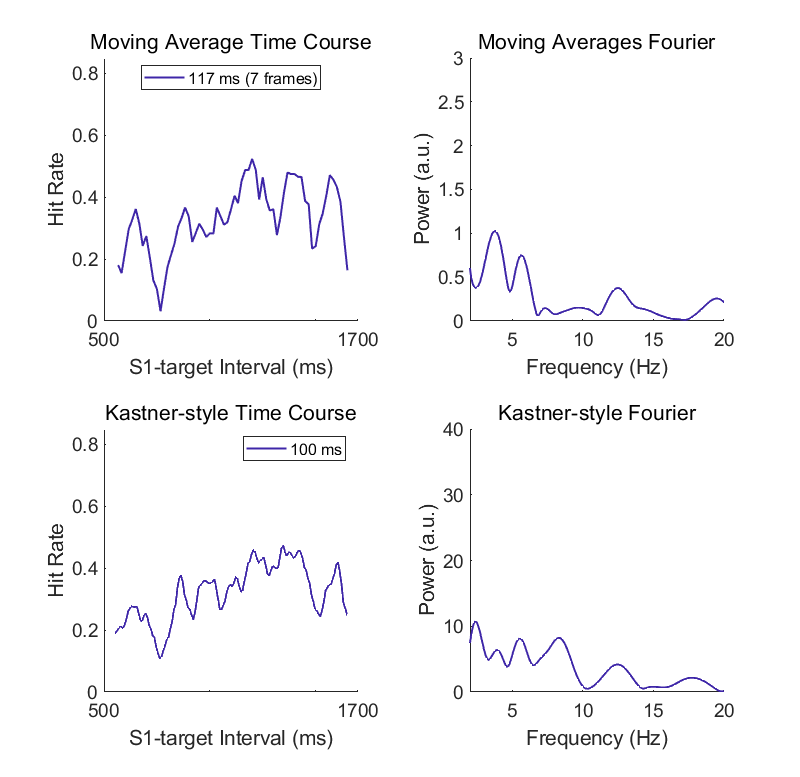

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, hitRateMoveMean117_Inv, "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0 0.85])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend("117 ms (7 frames)", "FontSize", 12, "Location", "Best")
nexttile
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean117_Inv), "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xlim([2 20])
    ylim([0 3])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), hitRateKastner100Smooth_Inv, "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0 0.85])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend("100 ms", "FontSize", 12, "Location", "Best")
nexttile
    plot(xValsKastnerHP, abs(FFT_hitRateKastner100_Inv), "Color", myColor(256,:), "LineWidth", 1.5)
    box off
    xlim([2 20])
    ylim([0 40])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Invalid Hit Rate 100 msec.png", 'Resolution', 300)

### Invalid trial hit rate for 75–100 ms plots

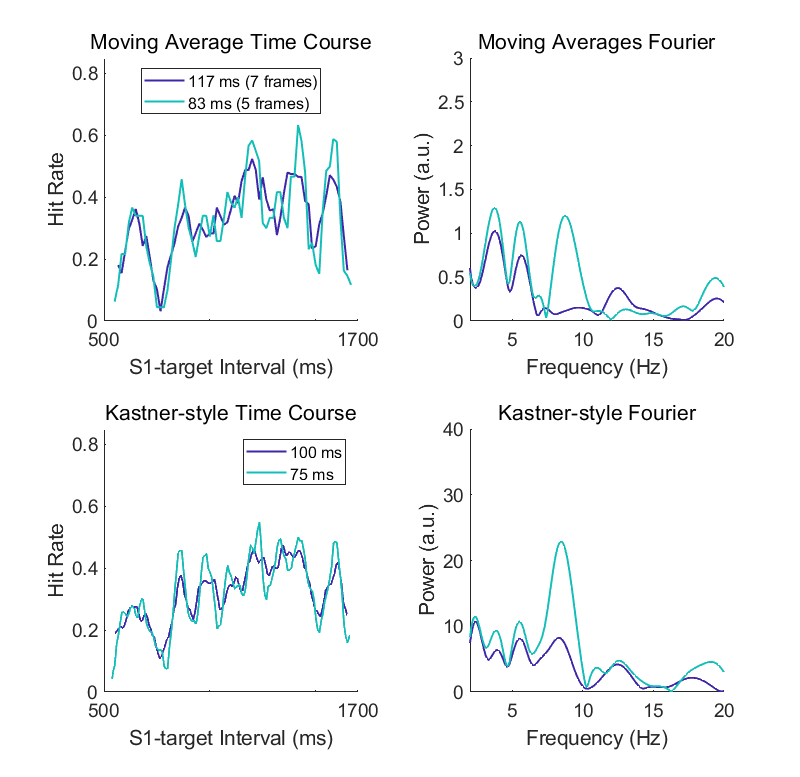

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, hitRateMoveMean117_Inv, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(uniqueS1_83, hitRateMoveMean83_Inv, "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0 0.85])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend(["117 ms (7 frames)", "83 ms (5 frames)"], "FontSize", 12, "Location", "Best")
nexttile
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean117_Inv), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean83_Inv), "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xlim([2 20])
    ylim([0 3])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), hitRateKastner100Smooth_Inv, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xStartKastner(2):xEndKastner(2), hitRateKastner75Smooth_Inv, "Color", myColor(128,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0 0.85])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend(["100 ms", "75 ms"], "FontSize", 12, "Location", "Best")
nexttile
    plot(xValsKastnerHP, abs(FFT_hitRateKastner100_Inv), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsKastnerHP, abs(FFT_hitRateKastner75_Inv), "Color", myColor(128,:), "LineWidth", 1.5)
    hold on
    hold off; box off
    xlim([2 20])
    ylim([0 40])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Invalid Hit Rate 75–100 msec.png", 'Resolution', 300)

### Invalid trial hit rate for 50–100 ms plots

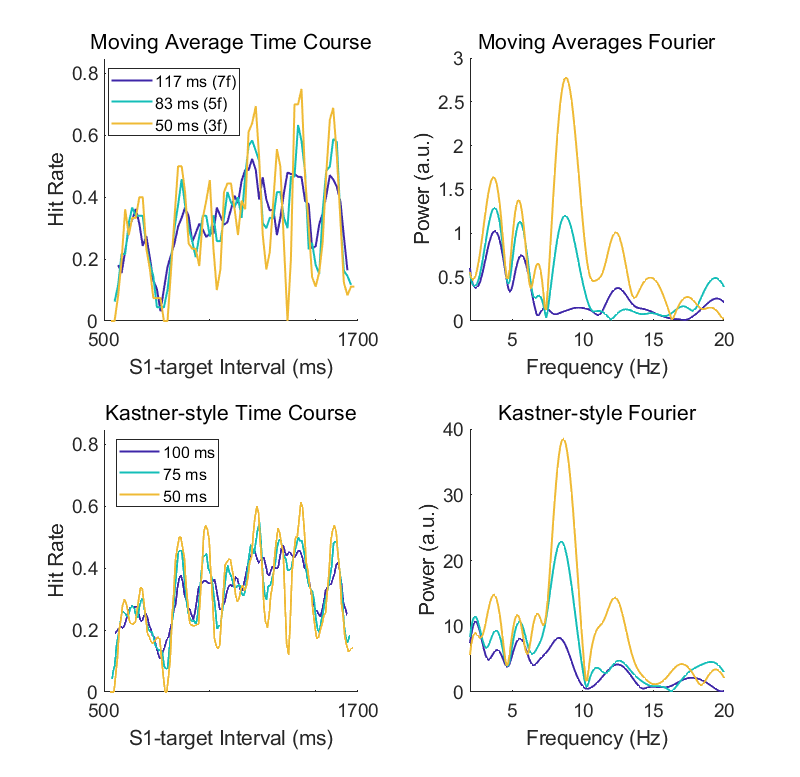

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, hitRateMoveMean117_Inv, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(uniqueS1_83, hitRateMoveMean83_Inv, "Color", myColor(128,:), "LineWidth", 1.5)
    plot(uniqueS1_50, hitRateMoveMean50_Inv, "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0 0.85])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend(["117 ms (7f)", "83 ms (5f)", "50 ms (3f)"], "FontSize", 12, "Location", "Best")
nexttile
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean117_Inv), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean83_Inv), "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xValsMoveMeanHP, abs(FFT_HitRateMoveMean50_Inv), "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xlim([2 20])
    ylim([0 3])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), hitRateKastner100Smooth_Inv, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xStartKastner(2):xEndKastner(2), hitRateKastner75Smooth_Inv, "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xStartKastner(1):xEndKastner(1), hitRateKastner50Smooth_Inv, "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([0 0.85])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Hit Rate")
    legend(["100 ms", "75 ms", "50 ms"], "FontSize", 12, "Location", "Best")
nexttile
    plot(xValsKastnerHP, abs(FFT_hitRateKastner100_Inv), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsKastnerHP, abs(FFT_hitRateKastner75_Inv), "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xValsKastnerHP, abs(FFT_hitRateKastner50_Inv), "Color", myColor(50,:), "LineWidth", 1.5)
    hold on
    hold off; box off
    xlim([2 20])
    ylim([0 40])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Invalid Hit Rate 50–100 msec.png", 'Resolution', 300)

### Reaction time for invalid trials

correctInvalidRT  = trialRT(correctInvalid);
correctInvalidS1RT = nan(length(uniqueS1), 1);

for n = 1:length(uniqueS1)
    loopInvalid = ismember(correctInvalidS1, uniqueS1(n));
    correctInvalidS1RT(n) = mean(correctInvalidRT(loopInvalid));
end

RTMoveMean50_Inv = movmean(correctInvalidS1RT, 3, "omitnan");
RTMoveMean83_Inv = movmean(correctInvalidS1RT, 5, "omitnan");
RTMoveMean117_Inv = movmean(correctInvalidS1RT, 7, "omitnan");

RTMoveMean50_Inv = RTMoveMean50_Inv(2:end-1);
RTMoveMean83_Inv = RTMoveMean83_Inv(3:end-2);
RTMoveMean117_Inv = RTMoveMean117_Inv(4:end-3);

RTMoveMean50H_Inv = RTMoveMean50_Inv .* hann(height(RTMoveMean50_Inv));
RTMoveMean83H_Inv = RTMoveMean83_Inv .* hann(height(RTMoveMean83_Inv));
RTMoveMean117H_Inv = RTMoveMean117_Inv .* hann(height(RTMoveMean117_Inv));

RTMoveMean50HP_Inv = [RTMoveMean50H_Inv; zeros(530, 1)];
RTMoveMean83HP_Inv = [RTMoveMean83H_Inv; zeros(532, 1)];
RTMoveMean117HP_Inv = [RTMoveMean117H_Inv; zeros(534, 1)];

FFT_RTMoveMean50_Inv = fft(RTMoveMean50HP_Inv, signalLengthExp);
FFT_RTMoveMean83_Inv = fft(RTMoveMean83HP_Inv, signalLengthExp);
FFT_RTMoveMean117_Inv = fft(RTMoveMean117HP_Inv, signalLengthExp);

RTKastner50_Inv = nan(1150, 1);
RTKastner75_Inv = nan(1125, 1);
RTKastner100_Inv = nan(1100, 1);

for n = 1:1150
    window50 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(1) + n - 1;
    RTKastner50_Inv(n) = mean(trialRT(window50 & correctInvalid));  
end
for n = 1:1125
    window75 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(2) + n - 1;
    RTKastner75_Inv(n) = mean(trialRT(window75 & correctInvalid));  
end
for n = 1:1100
    window100 = S1Timing >= startWindow + n - 1 & S1Timing <= endWindow(3) + n - 1;
    RTKastner100_Inv(n) = mean(trialRT(window100 & correctInvalid));  
end

RTKastner50Smooth_Inv = movmean(RTKastner50_Inv, 25, "omitnan");
RTKastner75Smooth_Inv = movmean(RTKastner75_Inv, 25, "omitnan");
RTKastner100Smooth_Inv = movmean(RTKastner100_Inv, 25, "omitnan");

RTKastner50H_Inv = RTKastner50Smooth_Inv .* hann(height(RTKastner50Smooth_Inv));
RTKastner75H_Inv = RTKastner75Smooth_Inv .* hann(height(RTKastner75Smooth_Inv));
RTKastner100H_Inv = RTKastner100Smooth_Inv .* hann(height(RTKastner100Smooth_Inv));

RTKastner50_Inv = [RTKastner50H_Inv; zeros(8850, 1)];
RTKastner75_Inv = [RTKastner75H_Inv; zeros(8875, 1)];
RTKastner100_Inv = [RTKastner100H_Inv; zeros(8900, 1)];

FFT_RTKastner50_Inv = fft(RTKastner50_Inv);
FFT_RTKastner75_Inv = fft(RTKastner75_Inv);
FFT_RTKastner100_Inv = fft(RTKastner100_Inv);

### Reaction time for 50–100 ms plots

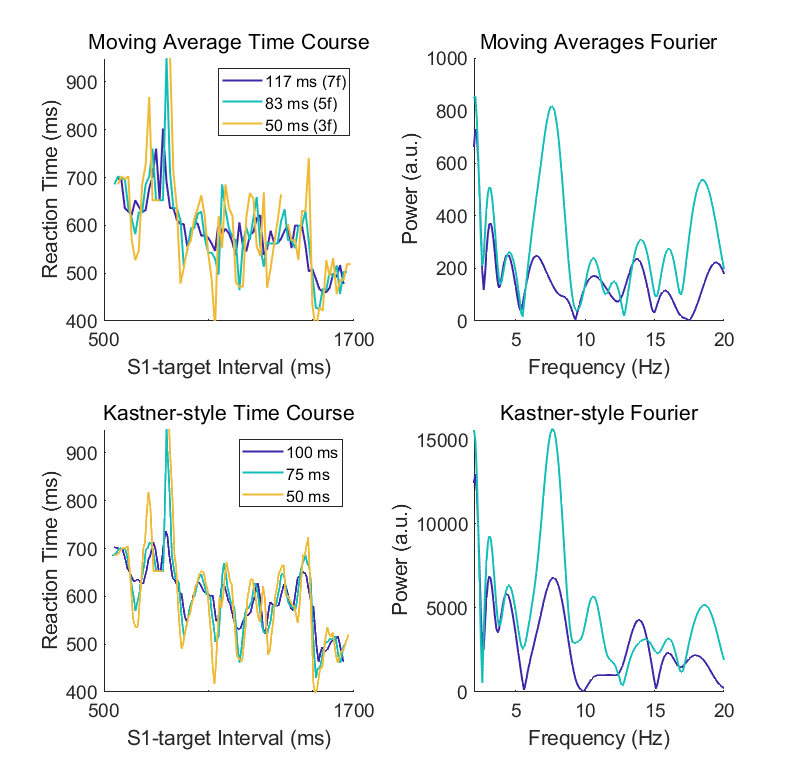

figure('Units', 'inches', 'OuterPosition', [0.5, 0.5, 8.5, 8.5])
tiledlayout(2, 2);
nexttile
    plot(uniqueS1_117, RTMoveMean117_Inv, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(uniqueS1_83, RTMoveMean83_Inv, "Color", myColor(128,:), "LineWidth", 1.5)
    plot(uniqueS1_50, RTMoveMean50_Inv, "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([400 950])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Average Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Reaction Time (ms)")
    legend(["117 ms (7f)", "83 ms (5f)", "50 ms (3f)"], "FontSize", 12, "Location", "best")
nexttile
plot(xValsMoveMeanHP, abs(FFT_RTMoveMean117_Inv), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsMoveMeanHP, abs(FFT_RTMoveMean83_Inv), "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xValsMoveMeanHP, abs(FFT_RTMoveMean50_Inv), "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xlim([2 20])
    % ylim([0 200])
    ax = gca;
    ax.FontSize = 14;
    title("Moving Averages Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
nexttile
    plot(xStartKastner(3):xEndKastner(3), RTKastner100Smooth_Inv, "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xStartKastner(2):xEndKastner(2), RTKastner75Smooth_Inv, "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xStartKastner(1):xEndKastner(1), RTKastner50Smooth_Inv, "Color", myColor(50,:), "LineWidth", 1.5)
    hold off; box off
    xticks([500 1000 1500 1700])
    xticklabels([500, "", "", 1700])
    xtickangle(0)
    xlim([500 1700])
    ylim([400 950])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Time Course", "FontSize", 16, "FontWeight", "normal")
    xlabel("S1-target Interval (ms)")
    ylabel("Reaction Time (ms)")
    legend(["100 ms", "75 ms", "50 ms"], "FontSize", 12, "Location", "best")
nexttile
    plot(xValsKastnerHP, abs(FFT_RTKastner100_Inv), "Color", myColor(256,:), "LineWidth", 1.5)
    hold on
    plot(xValsKastnerHP, abs(FFT_RTKastner75_Inv), "Color", myColor(128,:), "LineWidth", 1.5)
    plot(xValsKastnerHP, abs(FFT_RTKastner50_Inv), "Color", myColor(50,:), "LineWidth", 1.5)
    hold on
    hold off; box off
    xlim([2 20])
    % ylim([0 3000])
    ax = gca;
    ax.FontSize = 14;
    title("Kastner-style Fourier", "FontSize", 16, "FontWeight", "normal")
    xlabel("Frequency (Hz)")
    ylabel("Power (a.u.)")
exportgraphics(gcf, "Invalid RT 50–100 msec.png", 'Resolution', 300)

### Plot valid 50 ms Kastner time course for hit rate and reaction time

missRateKastner50Smooth = 1 - hitRateKastner50Smooth;

missRateKastner50Smooth =     0.3880
    0.3880
    0.3880
    0.3880
    0.3880
    0.3865
    0.3852
    0.3840
    0.3830
    0.3820


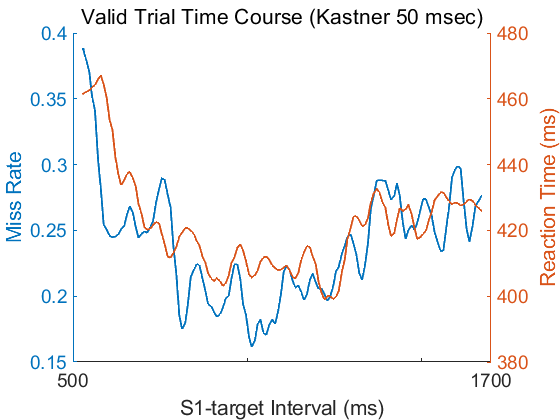


figure
yyaxis left
    plot(xStartKastner(1):xEndKastner(1), missRateKastner50Smooth, "LineWidth", 1.5)
    ax = gca;
    ax.FontSize = 14;
    ylabel("Miss Rate")
yyaxis right
    hold on
    plot(xStartKastner(1):xEndKastner(1), RTKastner50Smooth, "LineWidth", 1.5)
hold off; box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])
ax = gca;
ax.FontSize = 14;
title("Valid Trial Time Course (Kastner 50 msec)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1-target Interval (ms)")
ylabel("Reaction Time (ms)")
exportgraphics(gcf, "Valid Time Courses Kastner 50 msec.png", 'Resolution', 300)

### Plot invalid 75 ms Kastner time course for hit rate and reaction time

missRateKastner75Smooth_Inv = 1 - hitRateKastner75Smooth_Inv;

missRateKastner75Smooth_Inv =     0.9590
    0.9524
    0.9467
    0.9417
    0.9373
    0.9333
    0.9298
    0.9267
    0.9238
    0.9212


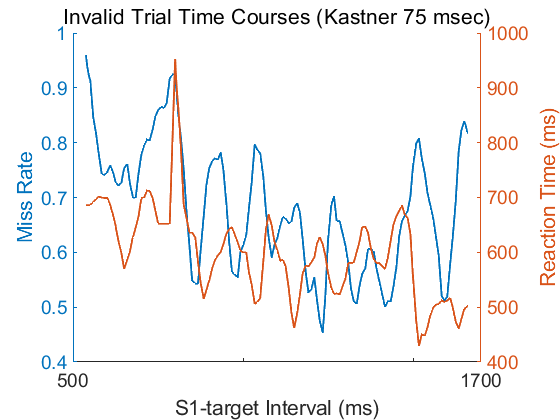


figure
yyaxis left
    plot(xStartKastner(2):xEndKastner(2), missRateKastner75Smooth_Inv, "LineWidth", 1.5)
    ax = gca;
    ax.FontSize = 14;
    ylabel("Miss Rate")
yyaxis right
    hold on
    plot(xStartKastner(2):xEndKastner(2), RTKastner75Smooth_Inv, "LineWidth", 1.5)
hold off; box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])
ax = gca;
ax.FontSize = 14;
title("Invalid Trial Time Courses (Kastner 75 msec)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1-target Interval (ms)")
ylabel("Reaction Time (ms)")
exportgraphics(gcf, "Invalid Time Courses Kastner 75 msec.png", 'Resolution', 300)

### Plot valid vs invalid 75 ms Kastner hit rate

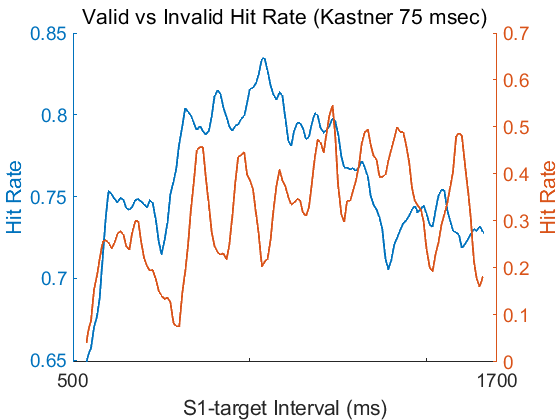

figure
yyaxis left
    plot(xStartKastner(2):xEndKastner(2), hitRateKastner75Smooth, "LineWidth", 1.5)
    ax = gca;
    ax.FontSize = 14;
    ylabel("Hit Rate")
yyaxis right
    hold on
    plot(xStartKastner(2):xEndKastner(2), hitRateKastner75Smooth_Inv, "LineWidth", 1.5)
    ylabel("Hit Rate")
hold off; box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])
ax = gca;
ax.FontSize = 14;
title("Valid vs Invalid Hit Rate (Kastner 75 msec)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1-target Interval (ms)")
exportgraphics(gcf, "Valid vs Invalid Hit Rate Kastner 75 msec.png", 'Resolution', 300)

### Plot valid vs invalid 75 ms Kastner reaction time

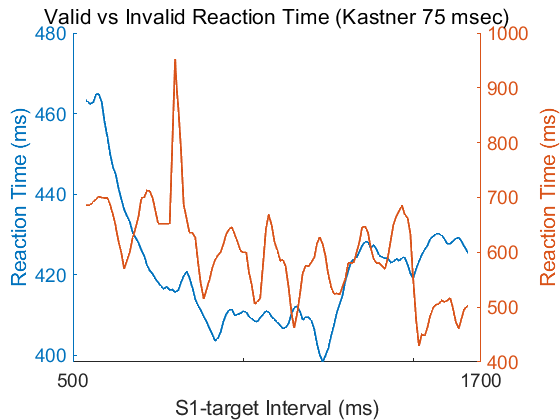

figure
yyaxis left
    plot(xStartKastner(2):xEndKastner(2), RTKastner75Smooth, "LineWidth", 1.5)
    ax = gca;
    ax.FontSize = 14;
    ylabel("Reaction Time (ms)")
yyaxis right
    hold on
    plot(xStartKastner(2):xEndKastner(2), RTKastner75Smooth_Inv, "LineWidth", 1.5)
hold off; box off
xticks([500 1000 1500 1700])
xticklabels([500, "", "", 1700])
xlim([500 1700])
ax = gca;
ax.FontSize = 14;
title("Valid vs Invalid Reaction Time (Kastner 75 msec)", "FontSize", 16, "FontWeight", "normal")
xlabel("S1-target Interval (ms)")
ylabel("Reaction Time (ms)")
exportgraphics(gcf, "Valid vs Invalid Reaction Time Kastner 75 msec.png", 'Resolution', 300)

### Plot invalid 75 ms Kastner Fouriers for hit rate and reaction time

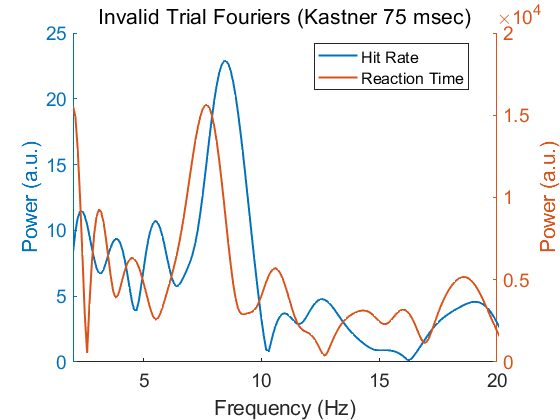

figure
yyaxis left
    plot(xValsKastnerHP, abs(FFT_hitRateKastner75_Inv), "LineWidth", 1.5)
    ax = gca;
    ax.FontSize = 14;
    ylabel("Power (a.u.)")
yyaxis right
    hold on
    plot(xValsKastnerHP, abs(FFT_RTKastner75_Inv), "LineWidth", 1.5)
hold off; box off
xlim([2 20])
ax = gca;
ax.FontSize = 14;
title("Invalid Trial Fouriers (Kastner 75 msec)", "FontSize", 16, "FontWeight", "normal")
xlabel("Frequency (Hz)")
ylabel("Power (a.u.)")
legend("Hit Rate", "Reaction Time", "FontSize", 12, "Location", "best")
exportgraphics(gcf, "Invalid Fouriers Kastner 75 msec.png", 'Resolution', 300)

### Plot valid vs invalid 50 ms Kastner hit rate Fouriers

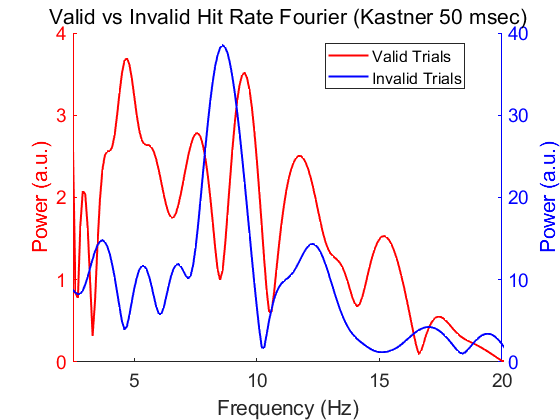

figure
yyaxis left
    plot(xValsKastnerHP, abs(FFT_hitRateKastner50), "r", "LineWidth", 1.5)
    ax = gca;
    ax.FontSize = 14;
    ylabel("Power (a.u.)")
yyaxis right
    hold on
    plot(xValsKastnerHP, abs(FFT_hitRateKastner50_Inv), "b", "LineWidth", 1.5)
    ylabel("Power (a.u.)")
hold off; box off
xlim([2.5 20])
ax = gca;
ax.FontSize = 14;
ax.YAxis(1).Color = 'r';
ax.YAxis(2).Color = 'b';
title("Valid vs Invalid Hit Rate Fourier (Kastner 50 msec)", "FontSize", 16, "FontWeight", "normal")
xlabel("Frequency (Hz)")
legend("Valid Trials", "Invalid Trials", "FontSize", 12, "Location", "best")
exportgraphics(gcf, "Valid vs Invalid Hit Rate Fourier Kastner 50 msec.png", 'Resolution', 300)